clc;clear all;
f = @(p,z) 1+(p(1)./z.^2) + (p(2)./(p(3)+z.^2));


T1 = readtable("AR4.xlsx");


xdata = T1.h_b;
ydata = T1.CL_IGE_CL_OGE;

x0 = [0,0,0];

p_opt1 = lsqcurvefit(f,x0,xdata,ydata);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('a = %.4f\n', p_opt1(1));

a = 0.0020


fprintf('b = %.4f\n', p_opt1(2));

b = 0.0077


fprintf('c = %.4f\n', p_opt1(3));

c = 0.0561



y_fit1 = f(p_opt1,xdata);


% figure;
% plot(xdata,ydata,'ro','MarkerFaceColor','r');
% hold on;
% plot(xdata,y_fit1,'b-','LineWidth',2);
% hold off;
% legend('True','Fit');
% xlabel('x');
% ylabel('y');
% title("AR4")
% grid on;

T2 = readtable("AR6.xlsx");


xdata = T2.h_b;
ydata = T2.CL_IGE_CL_OGE;

x0 = [0,0,0];

p_opt2 = lsqcurvefit(f,x0,xdata,ydata);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('a = %.4f\n', p_opt2(1));

a = 0.0012


fprintf('b = %.4f\n', p_opt2(2));

b = 0.0062


fprintf('c = %.4f\n', p_opt2(3));

c = 0.0702



y_fit2 = f(p_opt2,xdata);


% figure;
% plot(xdata,ydata,'ro','MarkerFaceColor','r');
% hold on;
% plot(xdata,y_fit2,'b-','LineWidth',2);
% hold off;
% legend('True','Fit');
% xlabel('x');
% ylabel('y');
% title("AR6")
% grid on;

T3 = readtable("AR8.xlsx");


xdata = T3.h_b;
ydata = T3.CL_IGE_CL_OGE;

x0 = [0,0,0];

p_opt3 = lsqcurvefit(f,x0,xdata,ydata);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('a = %.4f\n', p_opt3(1));

a = 0.0008


fprintf('b = %.4f\n', p_opt3(2));

b = 0.0052


fprintf('c = %.4f\n', p_opt3(3));

c = 0.0790



y_fit3 = f(p_opt3,xdata);


% figure;
% plot(xdata,ydata,'ro','MarkerFaceColor','r');
% hold on;
% plot(xdata,y_fit3,'b-','LineWidth',2);
% hold off;
% legend('True','Fit');
% xlabel('x');
% ylabel('y');
% title("AR8")
% grid on;

T4 = readtable("AR10.xlsx");


xdata = T4.h_b;
ydata = T4.CL_IGE_CL_OGE;

x0 = [0,0,0];

p_opt4 = lsqcurvefit(f,x0,xdata,ydata);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('a = %.4f\n', p_opt4(1));

a = 0.0009


fprintf('b = %.4f\n', p_opt4(2));

b = 0.0003


fprintf('c = %.4f\n', p_opt4(3));

c = 0.0011



y_fit4 = f(p_opt4,xdata);


% figure;
% plot(xdata,ydata,'ro','MarkerFaceColor','r');
% hold on;
% plot(xdata,y_fit4,'b-','LineWidth',2);
% hold off;
% legend('True','Fit');
% xlabel('x');
% ylabel('y');
% title("AR10")
% grid on;

T5 = readtable("AR12.xlsx");


xdata = T5.h_b;
ydata = T5.CL_IGE_CL_OGE;

x0 = [0,0,0];

p_opt5 = lsqcurvefit(f,x0,xdata,ydata);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('a = %.4f\n', p_opt5(1));

a = 0.0004


fprintf('b = %.4f\n', p_opt5(2));

b = 0.0040


fprintf('c = %.4f\n', p_opt5(3));

c = 0.0907



y_fit5 = f(p_opt5,xdata);


% figure;
% plot(xdata,ydata,'ro','MarkerFaceColor','r');
% hold on;
% plot(xdata,y_fit5,'b-','LineWidth',2);
% hold off;
% legend('True','Fit');
% xlabel('x');
% ylabel('y');
% title("AR12")
% grid on;

AR = [4 6 8 10 12];
p_opt_1 = [p_opt1(1); p_opt2(1); p_opt3(1); p_opt4(1); p_opt5(1)];
p_opt_2 = [p_opt1(2); p_opt2(2); p_opt3(2); p_opt4(2); p_opt5(2)];
p_opt_3 = [p_opt1(3); p_opt2(3); p_opt3(3); p_opt4(3); p_opt5(3)];

% figure;
% plot(AR,p_opt,'-o','LineWidth',1,'MarkerSize',6);
% legend ('Coeff a', 'Coeff b', 'Coeff c');
% xlabel("AR")
% ylabel("Coeff")
% grid on
% title("Variation of Coeff W.R.T AR")

coeff a = linear

coeff b = quad

coeff c = cubic

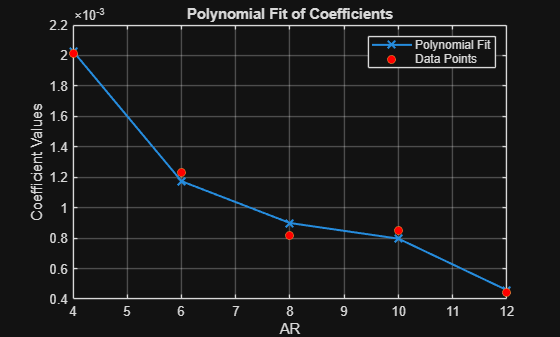

p1 = polyfit(AR,p_opt_1,3);
p_opt_p1 = polyval(p1,AR);

figure;
plot(AR, p_opt_p1, '-x', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;
plot(AR, p_opt_1, 'o', 'MarkerFaceColor', 'r');
hold off;
legend('Polynomial Fit', 'Data Points');
xlabel("AR");
ylabel("Coefficient Values");
title("Polynomial Fit of Coefficients");
grid on;

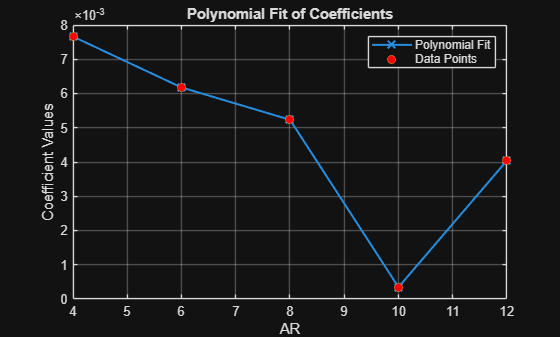

p2 = polyfit(AR,p_opt_2,4);
p_opt_p2 = polyval(p2,AR);

figure;
plot(AR, p_opt_p2, '-x', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;
plot(AR, p_opt_2, 'o', 'MarkerFaceColor', 'r');
hold off;
legend('Polynomial Fit', 'Data Points');
xlabel("AR");
ylabel("Coefficient Values");
title("Polynomial Fit of Coefficients");
grid on;

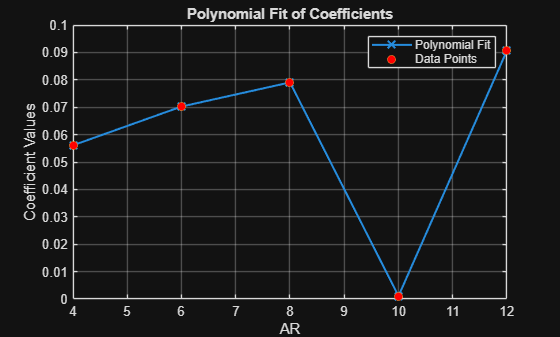

p3 = polyfit(AR,p_opt_3,4);
p_opt_p3 = polyval(p3,AR);

figure;
plot(AR, p_opt_p3, '-x', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;
plot(AR, p_opt_3, 'o', 'MarkerFaceColor', 'r');
hold off;
legend('Polynomial Fit', 'Data Points');
xlabel("AR");
ylabel("Coefficient Values");
title("Polynomial Fit of Coefficients");
grid on;